# Getting Started with IAM Explorer

## Using the data explorer App

The best way to explore databases is to simply use the app

## Create a Connection

The connection can be created with a default selected scenario or completely empty

c = iam.data.IIASAconnection('ngfs');

At any point in time, a user can view all the available environments in the database:

c.getEnvironments

ans = 15×5 table
                            productName                                  env                                uiUrl                                  name            scheme
    ___________________________________________________________    _______________    __________________________________________________    ___________________    ______

    "Netzero2040 Scenario Explorer"                                "netzero2040"      "https://data.ece.iiasa.ac.at/netzero2040"            "IXSE_NETZERO2040"       ""  
    "IAMC 1.5°C Scenario Explorer hosted by IIASA"                 "iamc15"           "https://data.ece.iiasa.ac.at/iamc-1.5c-explorer"     "IXSE_SR15"              ""  
    "DEEDS Scenario Explorer hosted by IIASA"                      "deeds"            "https://data.ene.iiasa.ac.at/deeds-explorer" 

## Exploring the databases

Although the Connection class allows you to perform various REST calls, the best way to explore a database is to use the enviornment class:

### View Models, Scenarios, and Variables

e = iam.IAMEnvironment(c)

e =   IAMEnvironment with properties:

    Environment: "NGFS Scenario Explorer"
         Models: [6×2 table]
      Scenarios: [27×2 table]
      Variables: [1759×4 table]
        Regions: [400×5 table]
        RunList: [45×17 table]
       Metadata: []


This object loads by default all the available Models, Scenarios, Variables, Regions and Runs in the database. For example, you can view all the models by running:

head(e.Variables)

ans = 8×4 table
     ID                           Name                           Unit ID          Unit       
    ____    _________________________________________________    _______    _________________

    2971    "Agricultural Demand"                                  112      "million t DM/yr"
     895    "Agricultural Demand|Crops"                            112      "million t DM/yr"
    2993    "Agricultural Demand|Crops|Energy"                     112      "million t DM/yr"
     881    "Agricultural Demand|Crops|Energy|1st generation"      112      "million t DM/yr"
     823    "Agricultural Demand|Crops|Energy|2nd generation"      112      "million t DM/yr"
    2789    "Agricultural Demand|Crops|Feed"                       112      "million t DM/yr"
    2738    "Agricultural Demand|Crops|Food"                       112      "million t DM/yr"
 

The environment also allows you to change the underlying database:

e.changeEnvironment('iamc15');
disp(e)

  IAMEnvironment with properties:

    Environment: "IAMC 1.5°C Scenario Explorer hosted by IIASA"
         Models: [25×2 table]
      Scenarios: [177×2 table]
      Variables: [598×4 table]
        Regions: [7×5 table]
        RunList: [416×17 table]
       Metadata: []



head(e.Models)

ans = 8×2 table
    ID                         Name                     
    __    ______________________________________________

    2     "AIM/CGE 2.0"                                 
    3     "AIM/CGE 2.1"                                 
    4     "C-ROADS-5.005"                               
    5     "GCAM 4.2"                                    
    6     "GENeSYS-MOD 1.0"                             
    7     "IEA Energy Technology Perspective Model 2017"
    8     "IEA World Energy Model 2017"                 
    9     "IMAGE 3.0.1"                                 


### Querying Datasets

There are different options to query and select timeseries within the database:

#### Both Model and Scenario are known:

In that case, one can request all the information from the database:

However, this query can be quite length as there are many different variables and regions that will be requested. Alternatively, the data can be fildtered down by "regions" and "variables as:

ts = e.getTimeSeries('model','AIM/CGE 2.0','scenario','ADVANCE_2020_1.5C-2100','regions','World','Variables','Emissions|CO2');

The data returned by the server is always stored in an array of IAM Timeseries objects. Each of these objects will allow you to automatically plot the data by running:

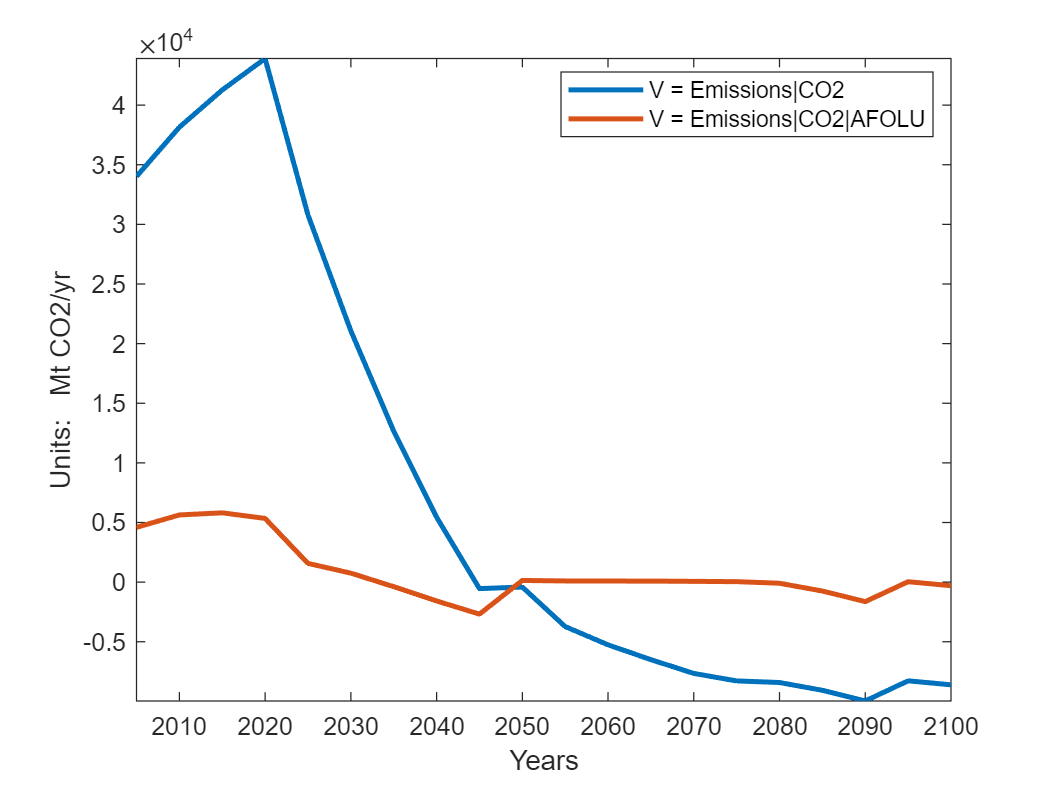

ts(1:2).plot('LineWidth',2);

#### Query by variable / region:

If neither model or scenario are known, it is also possible to query the data using only the filter values, for example:

e.changeEnvironment('ngfs');

ts = e.getTimeSeries('variables',"Emissions|CO", 'regions', "World");
[ts.Variable]'

ans = 690×1 string array
    "Emissions|CO2|Energy|Demand|Transportation|Passenger"
    "Emissions|CO2|Energy|Demand|Residential and Commercial|Commercial"
    "Emissions|CO|Energy|Supply"
    "Emissions|CO|Energy|Demand|Transportation"
    "Emissions|CO2|Energy|Demand|Industry|Steel"
    "Emissions|CO|Energy|Demand|Residential and Commercial"
    "Emissions|CO|Energy|Demand|Industry"
    "Emissions|CO2|Energy|Demand|Residential and Commercial"
    "Emissions|CO2|Energy|Demand|Industry|Other"
    "Emissions|CO2|Energy|Demand|Industry|Cement"
    "Emissions|CO2|Energy|Demand|Industry|Chemicals"
    "Emissions|CO2|Energy|Demand|Residential and Commercial|Residential"
    "Emissions|CO2|Energy|Demand|Transportation|Freight"
    "Emissions|CO"
    "Emissions|CO2|Energy|Supply|Heat"
    "Emissions|CO2|Energy|Demand|Industry"
    "Emissions|CO|Energy"
    "Emissions|CO2|AFOLU"
    "Emissions|CO|AFOLU"
    "Emissions|CO2|Energy|Supply"
    "Emissions|CO2|Energy|Demand|Transportation"
    "Emi

If multiple datrasets are returned, the plot command will plot all, or a subsection of them:

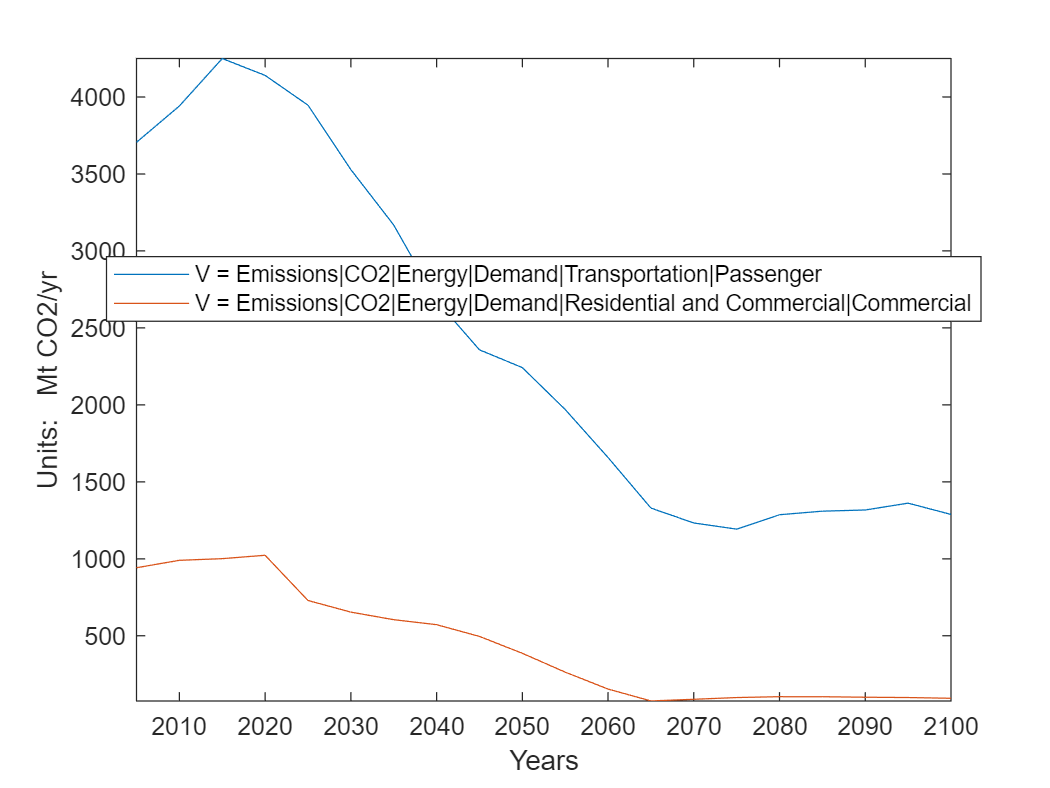

ts(1:2).plot();

For simplicity, the legend will only plot those variables that are different in each curve. For example, the previous plot have equal model, scenario, run, and region. So the legend only reports the different variable.

### Strict versus relaxed queries

By default, the queries will report any partial match to the dataset you enter. For example, the previous query returned all variables containing Emissions|CO. However, if we wanted a strict match to our inputs we could run:

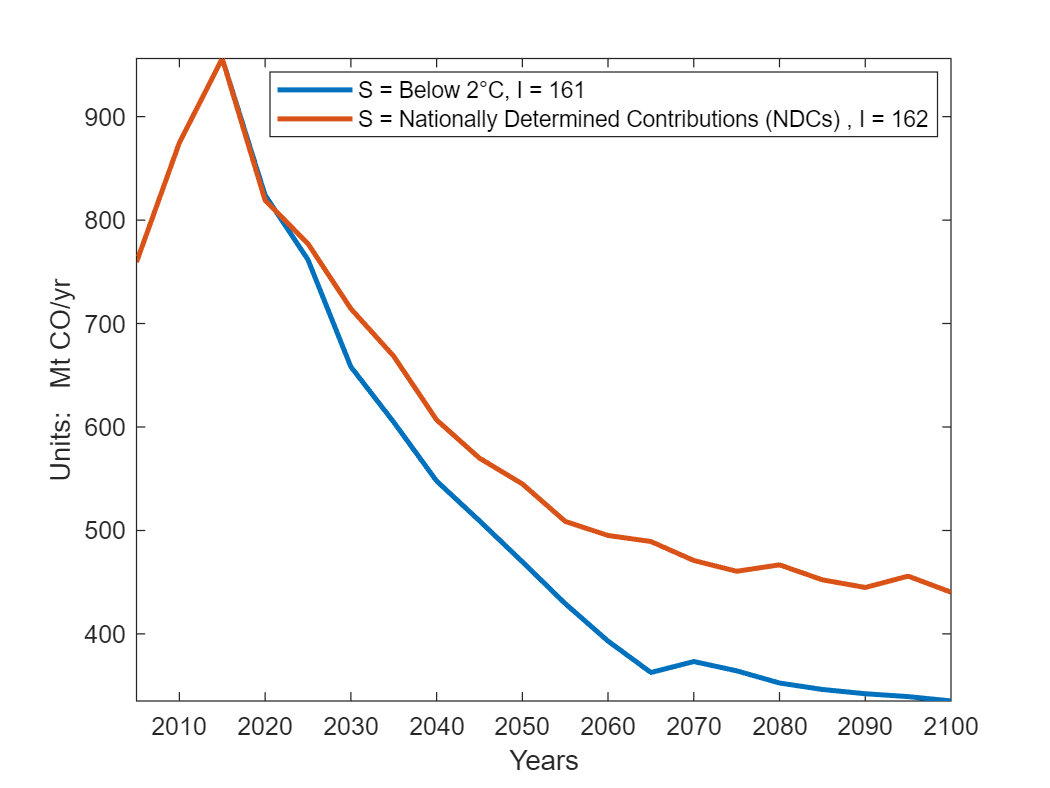

ts = e.getTimeSeries('variables',"Emissions|CO", 'regions', "World", 'strict',true);
ts(1:2).plot('LineWidth', 2);

### Filtering variables

The getTimeSeries only accepts a single "strict" command. However, we can still manually filter our results by running:

e.filterVariables('emissions',false)

ans = 165×1 string array
    "Carbon Intensity (Emissions|CO2/Final Energy)"
    "Carbon Intensity (Emissions|CO2/Primary Energy)"
    "Emissions|BC"
    "Emissions|BC|AFOLU"
    "Emissions|BC|Energy"
    "Emissions|BC|Energy|Demand|Industry"
    "Emissions|BC|Energy|Demand|Residential and Commercial"
    "Emissions|BC|Energy|Demand|Transportation"
    "Emissions|BC|Energy|Supply"
    "Emissions|C2F6"
    "Emissions|CF4"
    "Emissions|CH4"
    "Emissions|CH4|AFOLU"
    "Emissions|CH4|AFOLU|Agriculture"
    "Emissions|CH4|AFOLU|LULUCF"
    "Emissions|CH4|Buildings"
    "Emissions|CH4|Chemicals"
    "Emissions|CH4|Electricity"
    "Emissions|CH4|Energy"
    "Emissions|CH4|Energy|Demand|Industry"
    "Emissions|CH4|Energy|Demand|Industry|Chemicals|Ammonia|Beta"
    "Emissions|CH4|Energy|Demand|Industry|Chemicals|Beta"
    "Emissions|CH4|Energy|Demand|Industry|Non-ferrous metals|Aluminum|Beta"
    "Emissions|CH4|Energy|Demand|Industry|Other|Beta"
    "Emissions|CH4|Energy|Demand|Industry|

e.filterVariables('Emissions|CO',true)

ans = "Emissions|CO"

This same process can be done with regions

e.filterRegions('japan',false)

ans = 8×1 string array
    "Asian countries except Japan"
    "State of Japan"
    "REMIND-MAgPIE 2.1-4.2|Japan"
    "GCAM5.3_NGFS|Japan"
    "REMIND-MAgPIE 2.1-4.2 IntegratedPhysicalDamages (median)|Japan"
    "REMIND-MAgPIE 2.1-4.2 IntegratedPhysicalDamages (95th)|Japan"
    "State of Japan (downscaled)"
    "NiGEM NGFS v1.21|Japan"


e.filterRegions('State of Japan',true)

ans = "State of Japan"

and with model/scenarios to find out exact runs:

runs = e.filterRuns('model','GCAM','scenario','delayed','strict',false);
e.RunList(ismember(e.RunList.run_id,runs),1:8)

ans = 1×8 table
        model               scenario             scheme              annotation              metadata      run_id    model_id    scen_id
    ______________    ____________________    ____________    _________________________    ____________    ______    ________    _______

    "GCAM5.3_NGFS"    "Delayed transition"    {0×0 double}    "Phase 2 scenario upload"    {1×1 struct}     163         81         63   


## Working with the IAM Timeseries

### Plotting Data

A stack of IAMTimeseries objects can be plot in two main ways: line and bar plots. All plotting functions have two outputs: the array of graphics objects, and the legened. 

#### Line Plots

The data in the object can be plotted as a set of line plots. The plot funciton accepts the exact same options as the standard plot function in MATLAB. For example:

figure;
ts(1:2).plot('LineWidth',2);

#### Bar Plots

Alternatively, the data in the object can also be plotted as a set of bar plots. The bar funciton accepts the exact same options as the standard bar function in MATLAB.

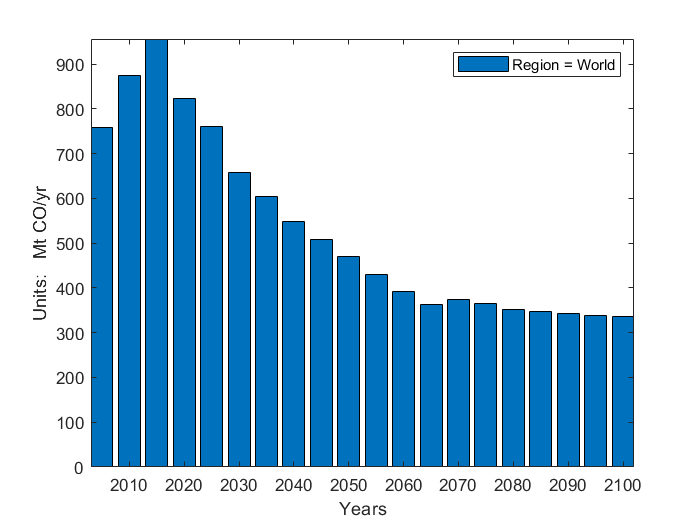

figure;
[~,l] = ts(1).bar();
l.Location = 'northeast';

One useful utility consists in making a stack plot of several data. For example:

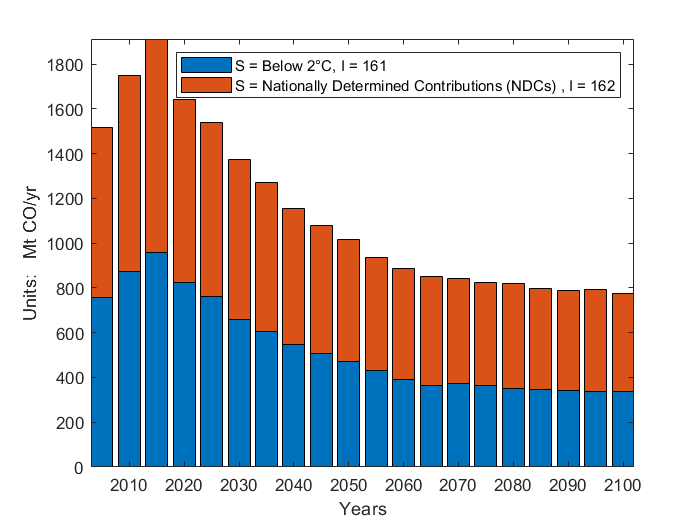

figure;
[h,l] = bar(ts(1:2),'stacked');
l.Location = 'northeast';